Some variables

%==========================================================================
%===========================================================response values
YESBLANK = 1; YESTARGET = 2; UNSURE = 4; BREAKINIT = -100; BREAKBLANK = -10; 
BREAKTARGET = -1; BREAKEXCL = -5; UNDEFINED = 0;

Here is our data

load('BAMOC_DEBUG_2021_6_23_17_57_52.mat')

PTB-INFO: Using modified PortAudio V19.6.0-devel, revision 396fe4b6699ae929d3a685b3ef8a7e97396139a4



contrasts = task.nVar(1).values;

trials = ana.task([ana.task.showGrating]==true);
trialscorrect = trials([trials.response]==YESTARGET);
trialswrong = trials([trials.response]==BREAKTARGET);

contrastTotal = [];
contrastCorrect = [];

for i = 1 : length(contrasts)
	tr = trialscorrect([trialscorrect.contrast] == contrasts(i));
	contrastCorrect(i) = length(tr);
	tr = trialswrong([trialswrong.contrast] == contrasts(i));
	contrastWrong(i) = length(tr);
	contrastTotal(i) = contrastWrong(i) + contrastCorrect(i);
end
contrasts = task.nVar(1).values;
total = contrastTotal;
correct = contrastCorrect;

Here are our model parameters

search.alpha = [min(contrasts):0.01:max(contrasts)];
search.beta = [ 0 : 0.1 : 30 ];
search.gamma = 0.5;
search.lambda = 0.02;
freeParameters = [1 1 0 0];
PF = @PAL_Quick;

Here we run the model

[params,b,c] = PAL_PFML_Fit(contrasts,correct,total,search,freeParameters,PF);
xrange = [min(contrasts):0.001:max(contrasts)];
fit = PAL_Quick(params,xrange);

And plot our result

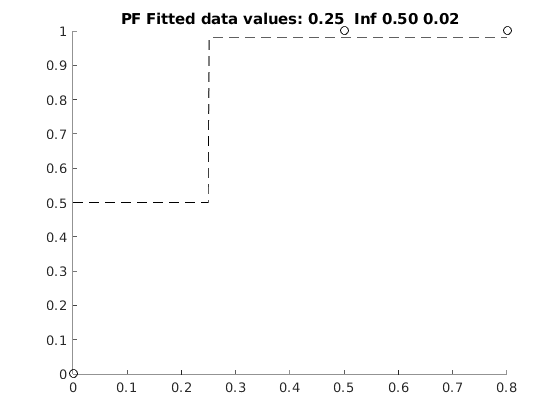

figure
hold on
plot(contrasts,(correct./total),'ko');
plot(xrange,fit,'k--');
title(['PF Fitted data values: ' num2str(params,'%.2f ')])